# Problem Hyperloop

## Introduction

In this exercise, you will use a Hyperloop model with a two-layer discretely supported beam subjected to a moving oscillator. You will perform eigen- and dynamic- analysis of the track model and visualize the results.

## Tutorial

### Creat the mesh geometry of the two-layered beam

clear % clear the variables in workspace
clc % clear the command shown in the command window

inp = get_input_hyper_loop(); % read input file
[nodeCoord]=node_coor(inp,1); % generate node coordinates, 1 means only one rail is modeled
btypr = inp.mesh.btypr; % beam element types for the rail: 1 for Euler, 2 for Timoshenko
[geo] = mesh_trk_full(btypr,btypr,nodeCoord); % generate the geometry properties

Open the 'get_input_hyper_loop' function to see the input parameters. What is the total length of the track (L)? What is the sleeper spacing (d)? What is the element length? 

What is the Young's modulus of the sleeper? (see the corresponding codes below) Compared to the Young's modulus of concrete material, is it too large or too small? Why do we define the value in this way?

-------------------------------------------------------------------

%MATERIAL SLEEPERS DATA 

in_data.mater(2).Data=[74.6e12; % E  [N/m^2]

---------------------------------------------------------------------

All the geometry information are stored in the variables 'geo.ND' and 'geo.EL'. You can visualize the model.

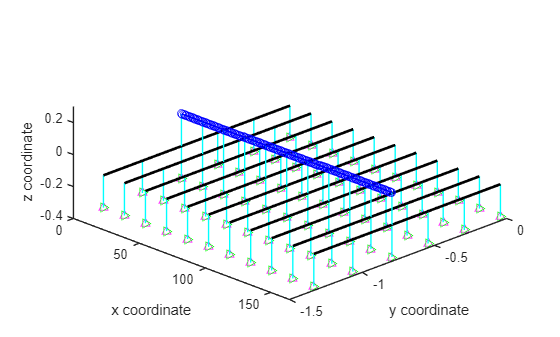

figure;
plot_geo(geo)
 xlim([0 165])

 Can you tell the different components, i.e., rail, sleepers, railpad and ballast? You can also see the boundary conditions: the bottom layer of the nodes are fixed to the ground (indicated by small triangles). You can interactive with the figure (rotate, zoom) using the buttons on the top right of the figure. 

### Generate the system matrices

mat_trk=form_mat_trk_2(inp,geo); % track matrices
mat_ws=form_mat_ws(inp); % mass (wheel) matrices

### Perform eigen-analysis

% retrieve the full matrices from the sparse matrices
% round the elements (just a numerical trick to make sure the 'eig' function gives the correct results)
Kr=round(full(mat_trk.K_reduced),-1);
Mr=round(full(mat_trk.M_reduced),13);
% solve the eigen-problem
[V,D]=eig(Kr,Mr);

'eig' function retures diagonal matrix `D` of  eigenvalues and full matrix `V` whose columns are the corresponding right eigenvectors, so that Kr`*V = Mr*V*D`. 

### Calculate and plot dispersion curves

Based on the mode shapes (eigenvectors) of the rail beam at different natural frequencies (eigenvalues), we can calculate the the dispersion curves. First, get the eigenvalues and eigenvectors for the rail.

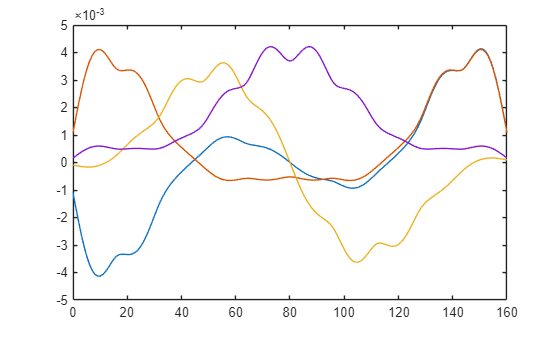

omega=abs(sqrt(diag(D))); % eigenvalues [rad/s]
indNodeRail = geo.ND(:,5) == 1; % get the index for the rail nodes
x_rail = geo.ND(indNodeRail,2); % get the x-coordinate for the rail
phi_rail = V(1:2:sum(indNodeRail == 1)*2,:); % get the mode shapes, we only extract the translational mode shapes
% plot the first four mode shapes of the rail
figure;
plot(x_rail, phi_rail(:,1:4));

Now we perform spectrum analysis on each mode shape to get its correponding wavelength (wavenumber). To make sure the spectrum has enough resolution, we first need to interpolate the mode shapes.

% interpolate mode shapes
nq = 2048; % number of interpolation points
xq=linspace(x_rail(1),x_rail(end),nq); % query points for interpolation
Vq=interp1(x_rail,phi_rail,xq); % interpolate
% spectrum analysis
[V_spectrum,fv]=pwelch(Vq,nq,0,nq*4,1/mean(diff(xq)));

fv is a vector representing the wavelength in [m-1]. V_spectrum is a matrix, of which each column presents the spectrum for a mode shape.  

Now plot the mode shape spectrum for the first four modes.

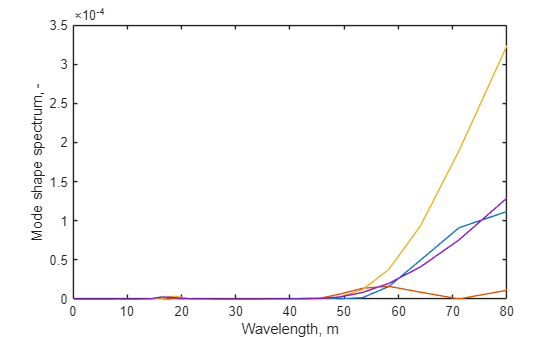

figure;
plot(1./fv,V_spectrum(:,1:4)); % use 1./fv to plot the wavelength in [m]
xlim([0 80])
xlabel('Wavelength, m')
ylabel('Mode shape spectrum, -')

Can you tell from the figure above the wavelength of each mode? Check the mode shapes of the first four modes (the previous figure) to see if the wavelengths are correct.

Now plot in 3D the mode shape spectrums with their corresponding natural frequencies.

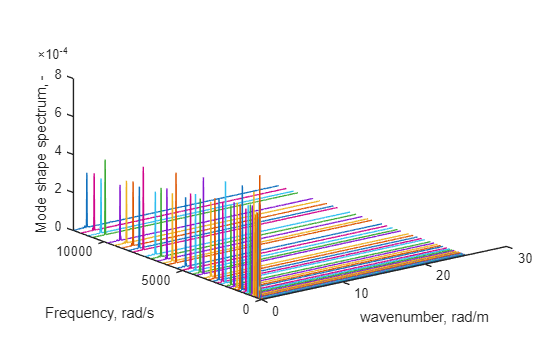

ind_fv = fv < 4; % define the maximum wavenumber to plot
fv_plt = fv(ind_fv);
wavenum_plt = 2*pi*fv_plt; % convert to wavenumber

figure
for mode_num = 1:2:100
plot3(wavenum_plt,omega(mode_num)*ones(length(wavenum_plt),1),V_spectrum(ind_fv,mode_num))
hold on
end
xlabel('wavenumber, rad/m')
ylabel('Frequency, rad/s')
zlabel('Mode shape spectrum, -')

Does the figure look like a dispersion curve? This figure is essentially a part of the dispersion curve that will be shown in the next step. You can rotate the plot to see more clearly. 

Use 'plt_dispersion' function to create a plot of the dispersion curve. 

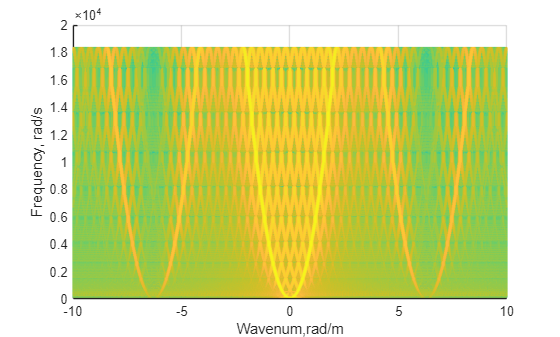

omega_bound = [10,2500]; % min and max frequencies to plot 

figure;
plt_dispersion(omega_bound,omega,V_spectrum,ind_fv,wavenum_plt)
xlim([-10 10])
hold on
xlabel('Wavenum,rad/m')
ylabel('Frequency, rad/s')

### Comaprison with ANSYS

Now you can proceed to the ANSYS tutorials for the same problem.

After performing the ANSYS tutorials, we can compare the results of the two models.

% frequencies of the ANSYS model , in [Hz]
freq_ansys = [
];
% wavenumbers of the ANSYS model, in [rad/m]
wavenum_ansys = [
];
% plot the dispersion
plot(wavenum_ansys,2.*pi().*freq_ansys,'r','LineWidth',3)

The red curve shown in the figure above represents the dispersion curve from the ansys model.

#### Exercises

- Change the Young's modulus of sleeper to a lower value (74.6e9). This will make the sleepers more flexible. Calcuate and plot the dispersion curve. Compare the dispersion curve with the rigid sleeper model and explain the differences between the two.

- Perform a dynamic analysis with the flexible sleeper model (use 'dynamic_main'). Plot the acceleration of the wheel (acc.w(:,1)). What is the wavelength of the signal?

- Change the ballast stiffness to half of the original value. Cacluate again the dispersion curve and time-domain respones of the wheel. What are the effects of ballast stiffness?

- Change the railpad to a stiffer one, with the stiffness of 1.3e9. Cacluate again the dispersion curve and time-domain respones of the wheel. What are the effects of railpad stiffness?